clear
clc

opts = optimoptions('fmincon','SpecifyObjectiveGradient',true,'Display','iter');

tic
[xv,Rv] = fmincon(@(x) objective(x),[10 8/3 28 1 1 1],[],[],[],[],[0 0 0 -10 -10 -10],[30 30 30 10 10 10],[],opts)

                                            First-order      Norm of
 Iter F-count            f(x)  Feasibility   optimality         step
    0       1    1.059805e+03    0.000e+00    5.831e+06
    1       2    2.210939e-07    0.000e+00    7.753e+03    3.696e+01
    2       3    2.215120e-07    0.000e+00    3.899e+01    1.030e-04
    3       4    3.227140e-07    0.000e+00    2.353e-01    1.895e-02
    4       7    1.713531e-03    0.000e+00    1.901e-01    4.562e-01
    5      11    8.159375e-03    0.000e+00    1.714e-01    8.992e-02
    6      12    7.488717e-03    0.000e+00    9.969e-02    1.349e-02
    7      13    3.345877e-03    0.000e+00    2.589e-02    1.478e-01
    8      14    2.099203e-03    0.000e+00    2.010e-02    1.052e-01
    9      15    9.013734e-04    0.000e+00    1.495e-02    1.874e-01
   10      16    4.349510e-04    0.000e+00    6.020e-03    1.556e-01
   11      17    2.003017e-04    0.000e+00    1.474e-03    1.579e-01
   12      18    9.486743e-05    0.000e+00    1

xv =     9.5471   27.0047    0.3626    1.1845    0.0544    1.7875


Rv = 1.3431e-08

toc

Elapsed time is 20.701050 seconds.


A = AutoDiff([xv(1) xv(2) xv(3) xv(4) xv(5) xv(6)]);

tic
[tf, yf] = ODE.rkf45(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 10, 0.01,  1e-9, A);
toc

Elapsed time is 1.620981 seconds.



L = sum((yf{end} - [0;0;0]).^2);

dL = full(getderivs(L))

dL = 1.0e-03 *

    0.0024   -0.0014   -0.0103   -0.0131    0.1646   -0.0170


L = getvalue(L)

L = 1.9727e-08


for i = 1:length(tf)
    yfv(:,i) = getvalue(yf{i});
    dyfv(:,:,i) = full(getderivs(yf{i}));
end

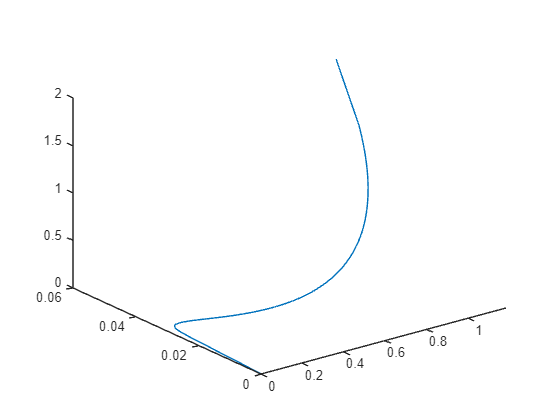

figure
plot3(yfv(1,:),yfv(2,:),yfv(3,:))

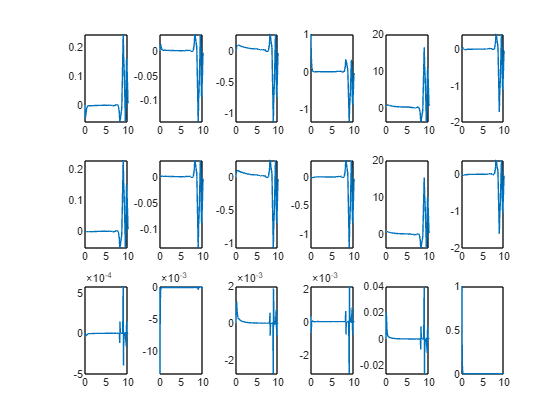


[nx,ny,~] = size(dyfv);

figure
k=0;
for i = 1:nx
    for j = 1:ny
        k=k+1;
        subplot(nx,ny,k)
        plot(tf,squeeze(dyfv(i,j,:)))
    end
end

function [L,dL] = objective(x)

A = AutoDiff([x(1) x(2) x(3) x(4) x(5) x(6)]);

[~, yf] = ODE.feuler(@(t,y) ODE.test.LorenzRHS(t,y,A(1),A(2),A(3)), [A(4);A(5);A(6)], 0, 10, 0.01, A);

L = sum((yf{end} - [0;0;0]).^2);

dL = full(getderivs(L));
L = getvalue(L);

end